# read color image

I0 = imread("mikasa1.png");

I0 = 1069×792×3 uint8 数组
I0(:,:,1) =

   120   120   120   120   121   123   123   124   125   127   128   129   131   132   132   135   135   136   136   136   136   136   136   136   136   137   137   139   139   139   139   139   137   139   139   139   142   143   144   145   145   147   149   149   149   150   150   149   149   148   149   149   150   148   148   147   143   142   142   142   140   139   137   137   137   137   137   136   135   133   133   132   133   133   133   133   133   136   136   137   137   137   137   137   137   137   136   134   134   134   134   137   137   140   142   143   147   150   152   152   150   149   148   148   148   149   149   149   150   150   152   153   153   156   156   156   156   156   156   153   153   153   152   152   151   152   152   151   150   147   145   143   140   139   137   136   136   136   136   135   135   136   137   137   137   136   135   134   134   134   134   134   134   134   134   134   133   133   133   130  

I = imresize(I0, 0.5);

I = 535×396×3 uint8 数组
I(:,:,1) =

   119   119   121   123   126   129   131   133   135   136   136   136   136   138   139   139   138   139   142   144   146   148   148   148   148   148   149   147   144   142   141   139   139   139   136   133   134   134   135   137   137   137   136   135   134   135   138   142   147   150   149   148   148   149   151   153   155   156   156   155   153   152   152   152   150   145   141   138   136   135   136   137   136   135   134   134   134   134   133   132   131   130   128   127   128   129   131   131   131   130   129   127   127   126   126   127   127   129   129   129   128   127   126   125   127   131   135   140   144   145   146   145   145   145   144   144   146   146   146   147   147   145   143   143   142   140   140   141   142   141   139   137   135   136   136   136   136   139   139   138   136   133   133   134   134   134   134   133   132   134   136   138   136   135   134   133   135   138   141   142   14

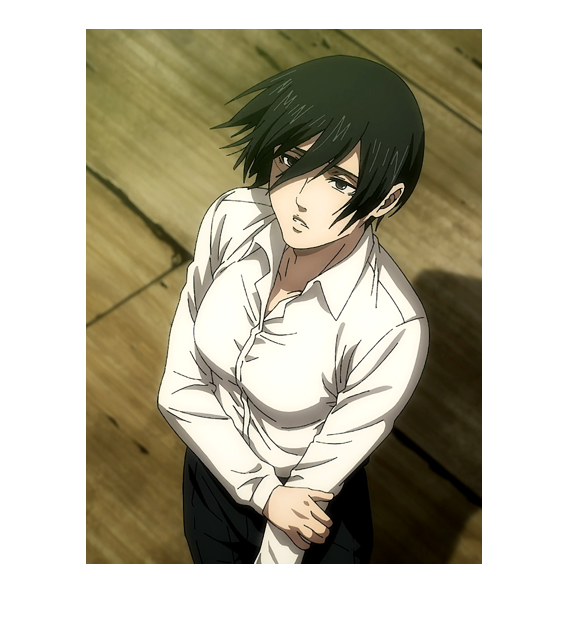

figure, imshow(I)

## change into grey image

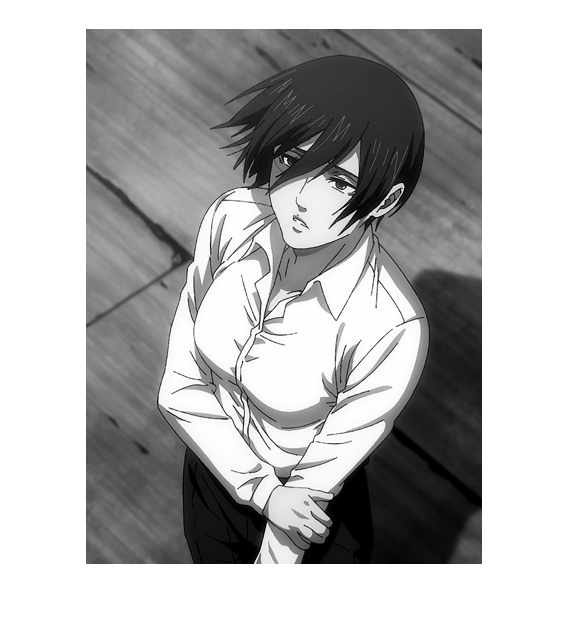

I1 = rgb2gray(I);
figure, imshow(I1)

## change into bw image

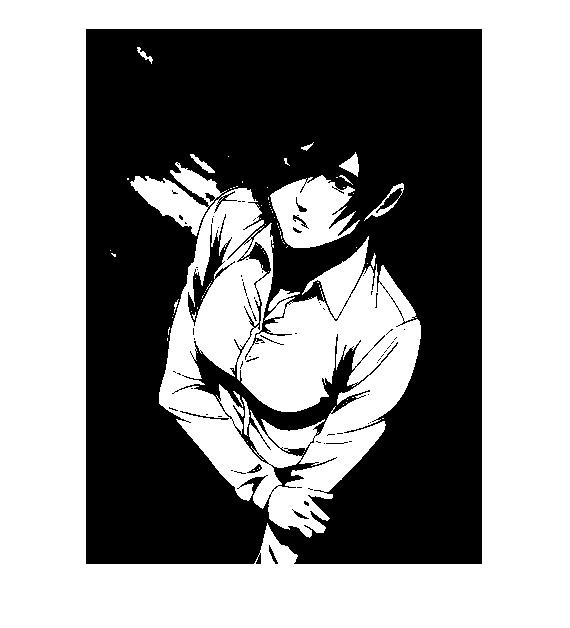

I2 = imbinarize(I1,graythresh(I1));
figure, imshow(I2)

## detect rim (sobel, prewitt, roberts, canny)

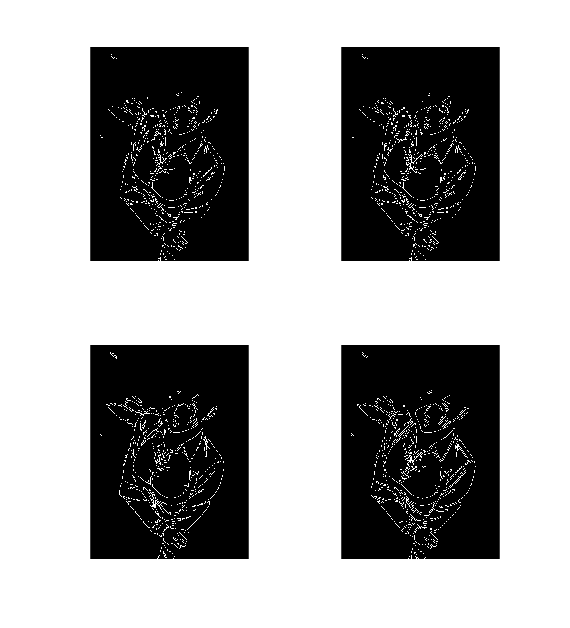

BW1 = edge(I2,'sobel');
BW2 = edge(I2, 'prewitt');
BW3 = edge(I2, 'roberts');
BW4 = edge(I2, 'canny');
subplot(221), imshow(BW1);
subplot(222), imshow(BW2);
subplot(223), imshow(BW3);
subplot(224), imshow(BW4);